Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

Fs = 1000;      % Sampling frequency
T = 1/Fs;       % Sampling period
L = 1500;       % Length of signal(占多少个采样点)
t = (0:L-1)*T;  % Time vector

signal

S = 0.7*cos(2*pi*50*t) + 0.2*sin(2*pi*50*t) + sin(2*pi*120*t);

add some noise

X = S + 2*randn(size(t));

plot

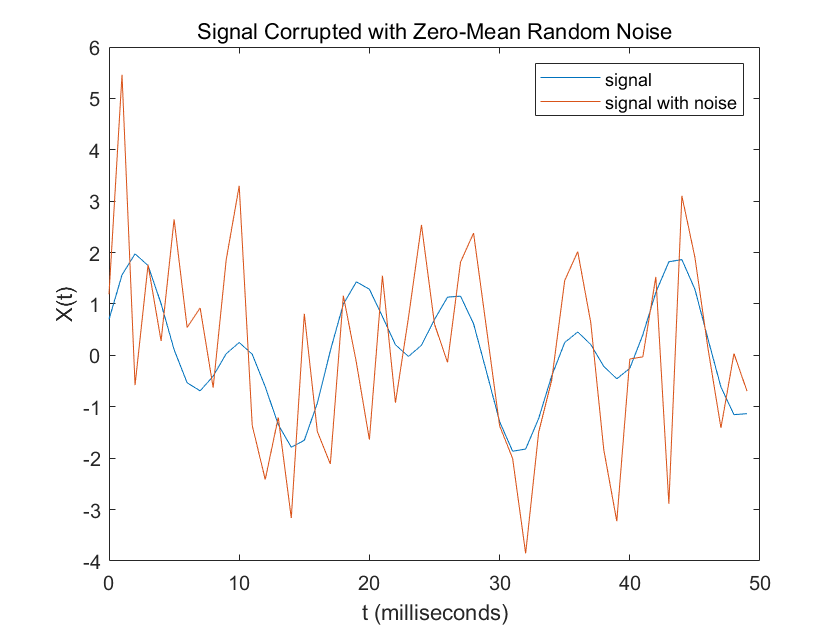

plot(1000*t(1:50), S(1:50), 1000*t(1:50), X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
legend('signal', 'signal with noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

Compute the Fourier transform

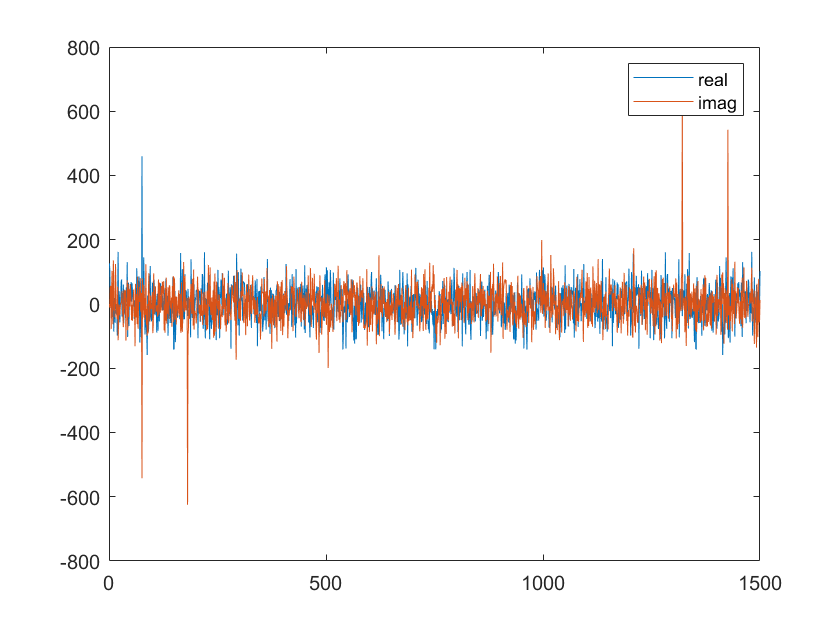

Y = fft(X);
w = 1:length(Y);
plot(w, real(Y), w, imag(Y));
legend('real', 'imag');

Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1.

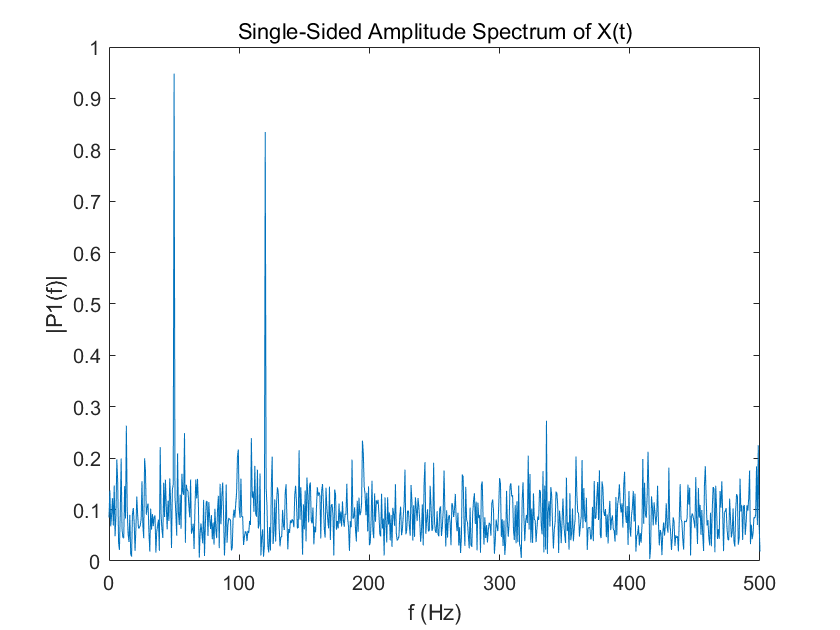

f = (0:L/2)*Fs/L;
plot(f, P1)
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Fourier transform of the original, uncorreupted signal and retrieve the exact amplitudes, 0.7 and 1.0.

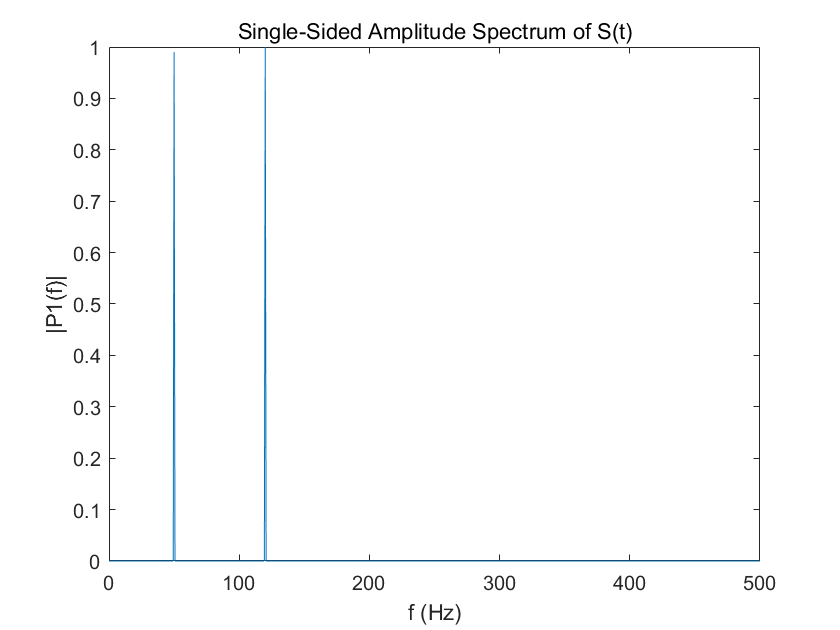

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f, P1)
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')